# **ME2201 TUTORIAL 6**

### **AYUSH SINGH - ME23B022**

This document has the solution to the 6 bar linkage analysis problem presented in tutorial 6, we will solve the problem using loop closure method of analysis. We will be using two loops to do so, one 4 bar loop O2ABO4 and the other slider crank loop O4CD. 

Using the first loop we shall find the angular velocity and anglar acceleration(if any) for link O4B which shall be then used for the second loop. 

The code has been written in MATLAB and many of the inbuilt functions are used to make it easier for us to analyse. 

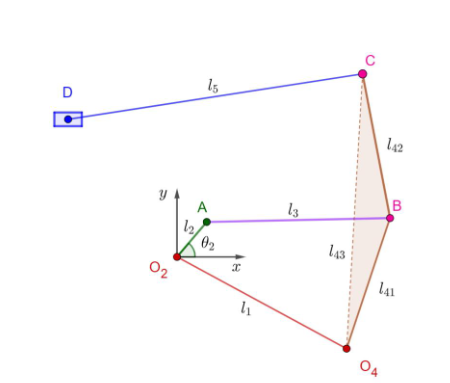

Starting by writing loop closure equations for the lower 4 bar mechanism. 

%This is the loop closure for 4 bar linkage
function y = TUT6(t, l, t2)  
    y(1) = l(2)*cos(t2) + l(3)*cos(t(1)) - l(4)*cos(t(2)) - 3.7;
    y(2) = l(2)*sin(t2) + l(3)*sin(t(1)) - l(4)*sin(t(2)) + 2;
end

Now we write the loop closure equation for finding angular velocity of link AB and O4B

%Loop closure equation for velocity
function z = loopfun_vel(t,l,t2,w, w0)
    z(1) = -w0*l(2)*sin(t2) - w(1)*l(3)*sin(t(1)) + w(2)*l(4)*sin(t(2));
    z(2) = w0*l(2)*cos(t2) + w(1)*l(3)*cos(t(1)) - w(2)*l(4)*cos(t(2));
end

Now we write the loop closure equation for finding the angular acceleration of links AB and O4B

%loop closure equation for acceleration
function q = loopfun_acc(a, l, t2, w, w0, a2,t)
    q(1) = -a2*l(2)*sin(t2)-a(1)*l(3)*sin(t(1))+a(2)*l(4)*sin(t(2))-l(2)*w0*w0*cos(t2)-l(3)*w(1)*w(1)*cos(t(1))-l(4)*w(2)*w(2)*cos(t(2));
    q(2) = a2*l(2)*cos(t2)+a(1)*l(3)*cos(t(1))-a(2)*l(4)*cos(t(2))-l(2)*w0*w0*sin(t2)-l(3)*w(1)*w(1)*sin(t(1))-l(4)*w(2)*w(2)*sin(t(2));
end

Now we have the loop closure equations we can work out for the position of point B solving for theta 3 and theta 4

l = [4.2;1;4;3;6.5;6]; % taking link lengths as input
t0 = [0.7*pi; 0.75*pi];% initial guess
w0 = -10; %CW angular velocity of link O2A
w3 = [4;4];% guess for angular velocity
a2 = 0; %angular velocity for link O2A
a0 = [1;11];% guess for angular acceleration 
d0 = [2;0.5];%guess for slider crank setup
v0 = [1;1];%guess for slider crank setup
acc0 = [1;1];% GUESS FOR SLIDER CRANK

ii = 1;

%the following code analyses the lower 4 bar linkage

for t2d = 0:5:360 
    t2 = t2d*pi/180;
    fn = @(t)loopfun_pos(t, l, t2);
    t = fsolve(fn,t0);
    for kk = 1:2 %ensuring there are no branch changes mid process
        if t(kk) < 0
            t(kk) = 2*pi + t(kk);
        end
    end
    om = @(w)loopfun_vel(t, l, t2, w, w0);
    w = fsolve(om, w3);

    ac = @(a)loopfun_acc(a, l, t2, w, w0, a2, t);
    a = fsolve(ac,a0);
    
    sc = @(d)slidercrank_pos(d,t,l);
    d = fsolve(sc, d0);

    sd = @(v)slidercrank_vel(l, v, d, w,t);
    v = fsolve(sd, v0);
    v_vec(:,ii) = v(1);

    sa = @(acc)slidercrank_acc(acc, t, v, w,a,l,d);
    acc = fsolve(sa, acc0);
    acc_vec(:,ii) = acc(1);

    d_vec(:,ii) = d(1);
    t2_vec(:,ii)= t2d;
    td_vec(:,ii) = t*180/pi;
    w_vec(:,ii) = w;
    a_vec(:,ii) = a;
    %the following variable assigning is done for further iterations
    t0 = t;
    a0 = a;
    w3 = w;
    d0 = d;
    v0 = v;
    ii = ii + 1;
end

%plotting curves
subplot(1,3,1)
plot(t2_vec, d_vec, 'b')
xlabel('Crank Angle \theta_2')
ylabel('X coordinate (in cm)')
subplot(1,3,2)
plot(t2_vec, v_vec, 'g')
xlabel('Crank Angle \theta_2')
ylabel('Velocity (in cm/s)')
subplot(1,3,3)
plot(t2_vec, acc_vec, 'r')
xlabel('Crank Angle \theta_2')
ylabel('Acceleration (in cm/s\^2)')
sgtitle('Parameters of Slider D with respect to Crank Angle \theta_2')

#### ANALYSING THE UPPER LOOP OF SLIDER CRANK NOW.

Now as we successfully found out the angular velcoity, acceleration of the driving link for Slider Crank mechanism we can move forward to analyse it's loop using the same loop closure analysis done here.

For that we need to write a loop closure equation for it.

%Loop closure equation for slider crank mechanism
function k = slidercrank_pos(d, t,l)
    k(1) = -3.7+d(1)+l(5)*cos(d(2))-l(6)*cos(t(2)+0.263);
    k(2) = 5 + l(5)*sin(d(2))-l(6)*sin(t(2)+0.263);
end

Writing a loop closure equation for velocity of slider crank 

%Loop closure equation for slider crank mechanism 
function s = slidercrank_vel(l, v, d, w)
    s(1) = v(1) - l(5)*v(2)*sin(d(2)) + l(6)*w(2)*sin(t(2)+0.263);
    s(2) = l(5)*v(2)*cos(d(2))-l(6)*w(2)*cos(t(2)+0.263);
end

Writng a loop closure equation for accelaration of slider crank

%loop closure equation for slider crank mechanism
function p = slidercrank_acc(acc, t, v, w, a, l, d)
    p(1) = acc(1) - l(5)*acc(2)*sin(d(2)) + l(6)*a(2)*sin(t(2)+0.263) - l(6)*w(2)*w(2)*cos(t(2)+0.263) - l(5)*v(2)*v(2)*cos(d(2));
    p(2) = l(5)*acc(2)*cos(d(2)) - l(6)*a(2)*sin(t(2) + 0.263) - l(6)*w(2)*w(2)*sin(t(2)+0.263) - l(5)*v(2)*v(2)*sin(d(2));
end

Now to our existing 'for' loop in the main function we will add the following code so that we can analyse our slider crank setup

sc = @(d)slidercrank_pos(d,t,l,);
d = fsolve(sc, d0);
d_vec(:,ii) = d(1);

sd = @(v)slidercrank_vel(l, v, d, w);
v = fsolve(sd, v0);
v_vec(:,ii) = v(1);

sa = @(acc)slidercrank_acc(acc, t, v, w,a,l,d);
acc = fsolve(sa, acc0);
acc_vec(:,ii) = acc(1);

The graphs that are produced via this method is shown here